# YOLOv2 Object Detection

# Part 2: Train and Evaluate a Model

Copyright 2018-2020 The MathWorks, Inc.

## 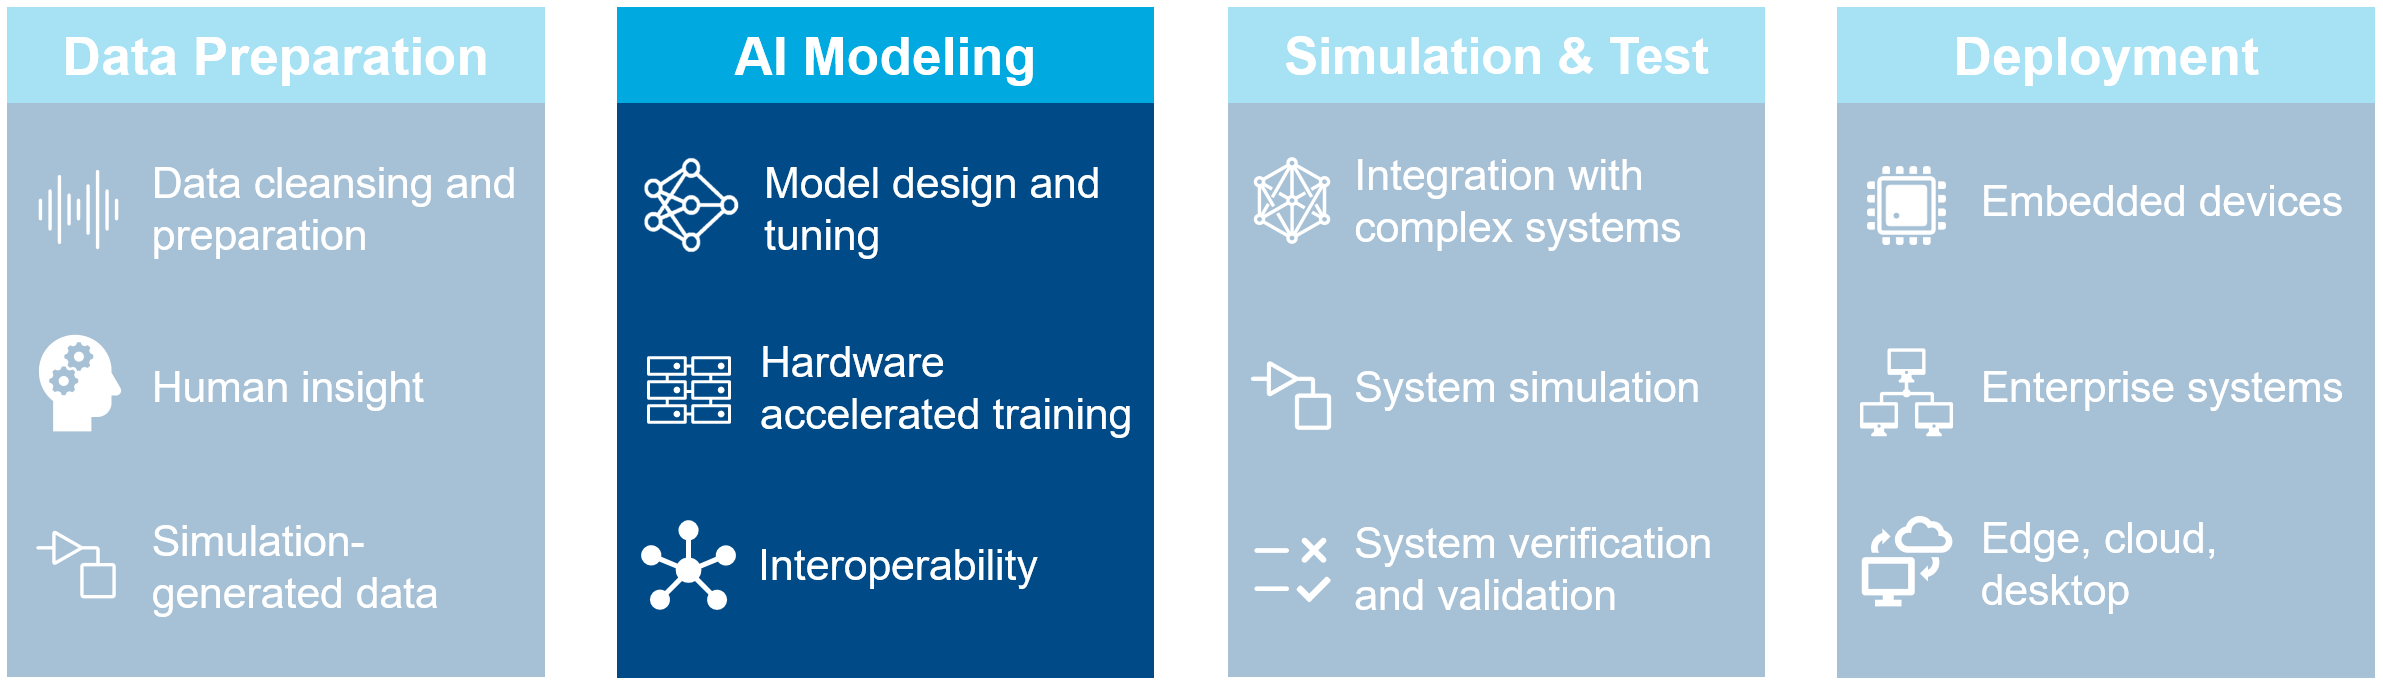

## Configure

Click on the checkboxes below to choose options for how to run this script.

doTraining = false;
importONNXNetworkLive = false;

Make sure we run this as a project.

try
    prj = currentProject;
catch
    open("YOLOv2ObjectDetection.prj");
    OpenPart2;
    prj = currentProject;
end

## **Load Data Set**

This example uses a small vehicle data set that contains 295 images. Each image contains one or two labeled instances of a vehicle. A small data set is useful for exploring the YOLO v2 training procedure, but in practice, more labeled images are needed to train a robust detector.  These data ship with the Deep Learning Toolbox examples.

if ~isfolder("vehicleDatasetImages")
    unzip("vehicleDatasetImages.zip")
end
data = load('vehicleDatasetGroundTruth.mat');

                                              imageFilename                                                 vehicle   
    __________________________________________________________________________________________________    ____________

    "E:\abhijit\DeepLearningSeminarR2020a\resnet50yolov2vehicledetector\vehicleImages\image_00001.jpg"    {1×4 double}
    "E:\abhijit\DeepLearningSeminarR2020a\resnet50yolov2vehicledetector\vehicleImages\image_00002.jpg"    {1×4 double}
    "E:\abhijit\DeepLearningSeminarR2020a\resnet50yolov2vehicledetector\vehicleImages\image_00003.jpg"    {1×4 double}
    "E:\abhijit\DeepLearningSeminarR2020a\resnet50yolov2vehicledetector\vehicleImages\image_00004.jpg"    {1×4 double}



vehicleDataset = data.vehicleDataset;
vehicleDataset.imageFilename = fullfile(prj.RootFolder, vehicleDataset.imageFilename);
disp(head(vehicleDataset, 4))

## Data Preparation

Split the data set into a training set for training the detector, and a test set for evaluating the detector. Select 85% of the data for training. Use the rest for evaluation.  Set random seed to ensure example training reproducibility.

rng default
cv = cvpartition(height(vehicleDataset), "Holdout", 0.15);
trainingData = vehicleDataset(cv.training, :);
testData = vehicleDataset(cv.test, :);

### **Datastores**

Datastores are an effective way to manage and work with large datasets. The datastore object creates a pointer to the location of the stored data and the data isn't read until a function is invoked to read it. That way, one does not need to load all the data into the memory while training. 

Use `imageDatastore` and `boxLabelDatastore` (new in R2019b!) to create datastores for loading the image and label data during training and evaluation.

% Training Datastore
imdsTrain = imageDatastore(trainingData{:, 'imageFilename'});
bldsTrain = boxLabelDatastore(trainingData(:, 'vehicle'));

% Testing Datastore
imdsTest = imageDatastore(testData{:, 'imageFilename'});
bldsTest = boxLabelDatastore(testData(:, 'vehicle'));

% Combine image and box label datastores.
trainingDatastore = combine(imdsTrain, bldsTrain);
% testDatastore = combine(imdsTest, bldsTest);

### Explore Data

Display one of the images from the data set to understand the type of images it contains.

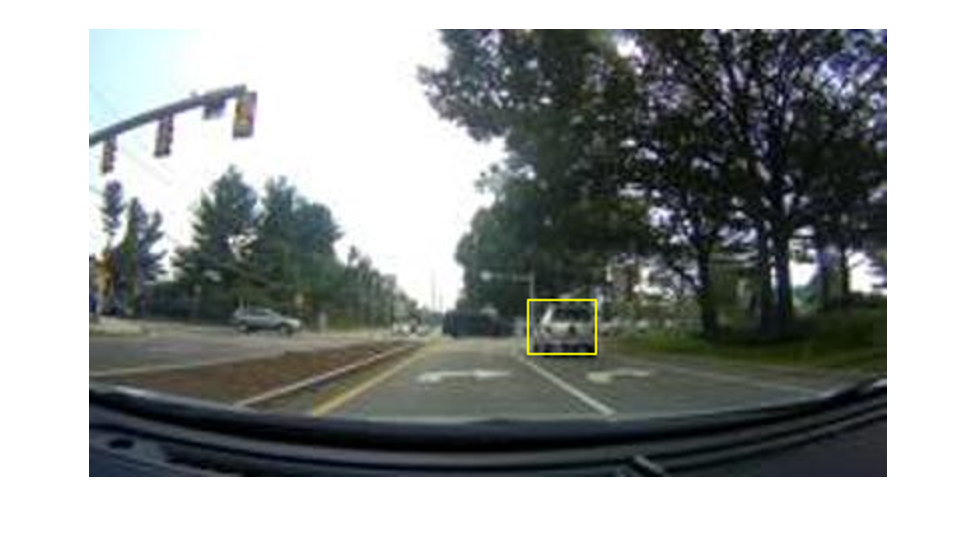

data = read(trainingDatastore);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I, 'Rectangle', bbox);
annotatedImage = imresize(annotatedImage, 2);
figure
imshow(annotatedImage)

## **Create a YOLOv2 Object Detection Network**

The YOLO v2 object detection network can be thought of as having two sub-networks. A feature extraction network, followed by a detection network.

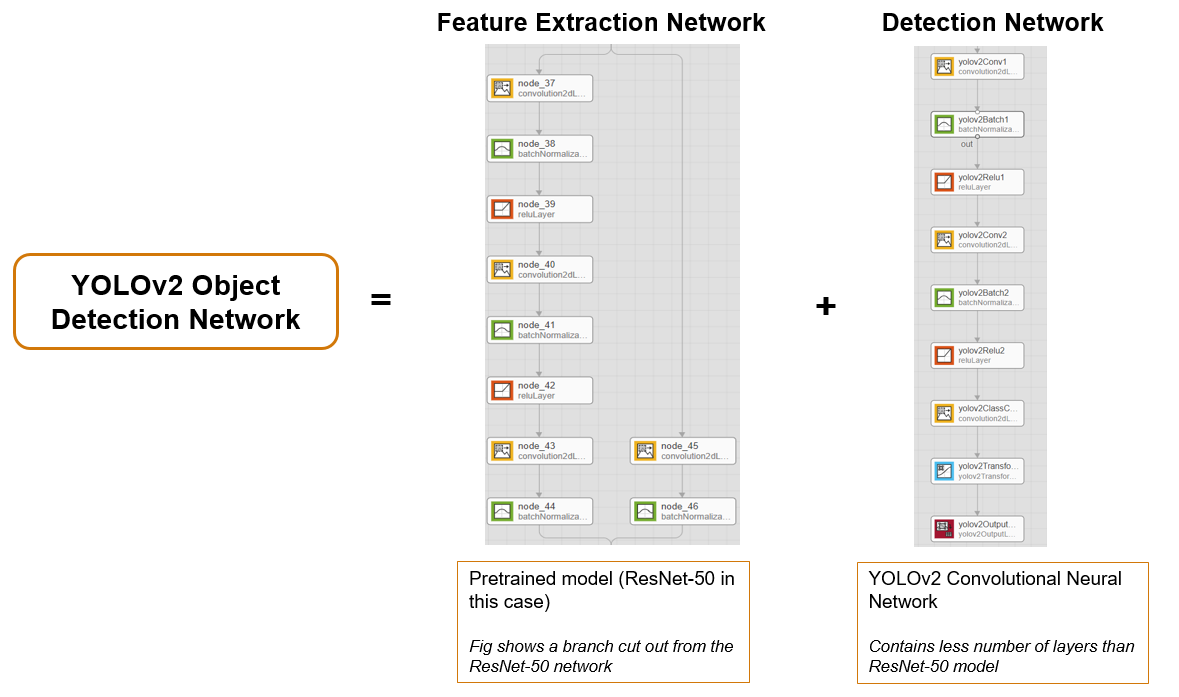

The feature extraction network is typically a pretrained CNN (see [Pretrained Deep Neural Networks](https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html) for more details). This example uses ResNet-50 for feature extraction. Other pretrained networks such as MobileNet v2 or ResNet-18 can also be used depending on application requirements. The detection sub-network is a small CNN compared to the feature extraction network and is composed of a few convolutional layers and layers specific for YOLO v2.

Steps:

- Import/ Access the feature extraction network

- Identify the feature layer and delete the layers after the feature  layer from the feature extraction network

- Create YOLO v2 Detection Sub-Network

- Connect the detection network with the feature extraction network

### 1 - Import the Feature Extraction Network

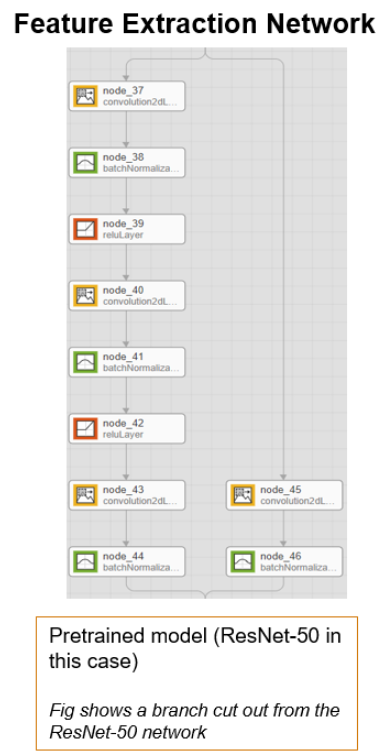

First, specify the backend network.  In this example, we'll use a pretrained [ResNet-50](https://s3.amazonaws.com/onnx-model-zoo/resnet/resnet50v1/resnet50v1.onnx) (release 1.3 on the model page [https://github.com/onnx/models/tree/master/vision/classification/resnet/resnet50](https://github.com/onnx/models/tree/master/vision/classification/resnet/resnet50) ) model as backend to train Yolov2 and import it from the [ONNX Model Zoo](https://github.com/onnx/models).

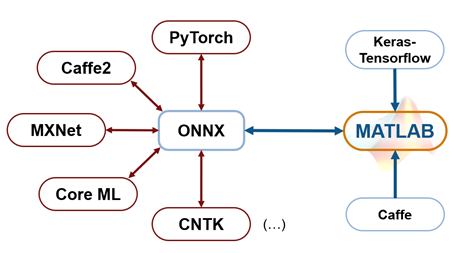

if importONNXNetworkLive
    s = load("classnames.mat")
    classNames = s.classNames;
    baseNetwork = importONNXNetwork('model.onnx', 'OutputLayerType', 'classification', 'classNames', classNames);
else
    load("baseNetwork.mat")
end

s = struct with fields:
    classNames: {1000×1 cell}


Open the Deep Network designer from the apps tab or from running [`deepNetworkDesigner`](matlab:deepNetworkDesigner).

Small numeric differences are often seen when models are exchanged across different frameworks. * It's not recommened to suppress this warning!*

### 2 - Remove Layers after Feature Extraction Layer

Identify the feature layer and delete the layers after the feature layer from the feature extraction network.  A good feature extraction layer for YOLOv2 is one where the output features width and height are between 8 and 16 times smaller than the input image.

In this case, the input dimension is [224 224 3]. So, search for something that is around 224/16 ~14. On analyzing the network, node_140 was found to be downsampled by a factor of 16. This amount of downsampling is a good tradeoff between spatial resolution and the strength of the extracted features (features extracted further down the network encode stronger image features at the cost of spatial resolution). 

Choosing the optimal feature extraction layer requires empirical analysis and is another hyperparameter to tune.

*For models imported using importers, the layer names might be different. *

featureLayer = 'node_140';

Remove layers after node_140. This example used the DND app to remove the layers and save it as a modified file.   You can also choose to do these network manipulations programmatically. It might take some effort given the size of the network.

modified = load("resNet50ONNX.mat");
lgraph = modified.resNet50ONNX_modified;

### **3. Create YOLO v2 Detection Sub-Network**

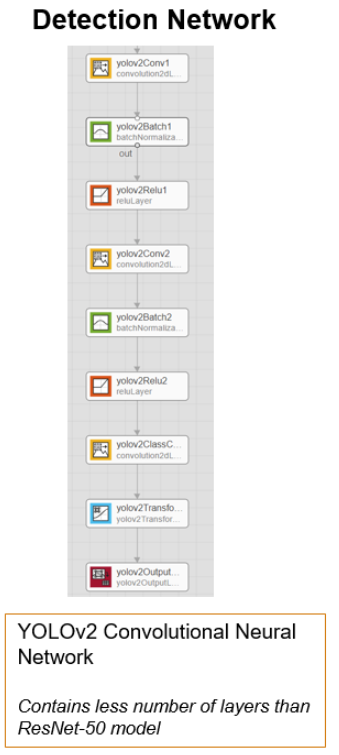

The detection subnetwork consists of groups of serially connected convolution, ReLU, and batch normalization layers. These layers are followed by a yolov2TransformLayer and a yolov2OutputLayer.

#### Create Convolution, ReLU, and Batch Normalization Layers

Set the convolution layer filter size to [3 3].  This size is common in CNN architectures. 

filterSize = [3 3];

Set the number of filters in the convolution layers to match the number of channels in the feature extraction layer output.

numFilters = 1024;

detectionLayers  = [    
    % group 1
    convolution2dLayer(filterSize, numFilters, "Name", "yolov2Conv1", "Padding", "same", "WeightsInitializer", @(sz)randn(sz)*0.01);
    batchNormalizationLayer("Name", "yolov2Batch1");
    reluLayer("Name", "yolov2Relu1");    
    % group 2
    convolution2dLayer(filterSize, numFilters, "Name", "yolov2Conv2", "Padding", "same", "WeightsInitializer", @(sz)randn(sz)*0.01)
    batchNormalizationLayer("Name", "yolov2Batch2")
    reluLayer("Name", "yolov2Relu2");
    ]

detectionLayers =   6x1 Layer array with layers:

     1   'yolov2Conv1'    Convolution           1024 3x3 convolutions with stride [1  1] and padding 'same'
     2   'yolov2Batch1'   Batch Normalization   Batch normalization
     3   'yolov2Relu1'    ReLU                  ReLU
     4   'yolov2Conv2'    Convolution           1024 3x3 convolutions with stride [1  1] and padding 'same'
     5   'yolov2Batch2'   Batch Normalization   Batch normalization
     6   'yolov2Relu2'    ReLU                  ReLU

#### **Define Anchor Boxes**

Anchor boxes are a set of predefined bounding boxes of a certain height and width. These boxes are defined to capture the scale and aspect ratio of specific object classes you want to detect and are typically chosen based on object sizes in your training datasets. During detection, the predefined anchor boxes are tiled across the image. The network predicts the probability and other attributes, such as background, intersection over union (IoU) and offsets for every tiled anchor box. The predictions are used to refine each individual anchor box. You can define several anchor boxes, each for a different object size. You can also learn more about how [anchor boxes work](https://www.mathworks.com/help/vision/ug/anchor-boxes-for-object-detection.html#mw_262f8815-db7b-4437-935c-cee8257778bc)

The anchor boxes should be selected based on the scale and size of objects in the training data. You can [Estimate Anchor Boxes Using Clustering](https://www.mathworks.com/help/vision/ug/estimate-anchor-boxes-from-training-data.html) (Computer Vision Toolbox) to determine a good set of anchor boxes based on the training data. 

For example, here's is a programmatic way to estimate anchor boxes from training data using the [`estimateAnchorBoxes`](https://www.mathworks.com/help/vision/ref/estimateanchorboxes.html) function, which uses the intersection-over-union (IoU) distance metric. Plug in the value of the input labels (bldsTrain in this case) and get the estimates for the anchor boxes.

The anchor box plays a pivotal role in the overall training accuracy results (as well as test results). After a few iterations (of estimating anchor box values and training the data), the best anchor boxes are: 

anchorBoxes = [43 59
               18 22
               23 29
               84 109];
numAnchors = size(anchorBoxes, 1);


There are five predictions per anchor box: 

- Predict the x, y, width, and height offset for each anchor.

- Predict the intersection-over-union with ground truth boxes.

numPredictionsPerAnchor = 5;

*There might be other anchor box values that might produce better results. These values provided good results given the training options and other hyperparameter values.*

#### Create and Add the Last Layers

Use the `convolution2dLayer`, `yolov2Transform`, and `yolov2Output` layers.

% Define the number of object classes to detect.
numClasses = width(vehicleDataset)-1;

% Number of filters in last convolution layer.
outputSize = numAnchors*(numPredictionsPerAnchor + numClasses);

finalLayers = [
    convolution2dLayer(1,outputSize, "Name", "yolov2ClassConv", "WeightsInitializer", @(sz)randn(sz)*0.01)
    yolov2TransformLayer(numAnchors, "Name", "yolov2Transform")
    yolov2OutputLayer(anchorBoxes, "Name", "yolov2OutputLayer")];

Add the last layers to network.

detectionLayers = [detectionLayers
                   finalLayers]

detectionLayers =   9x1 Layer array with layers:

     1   'yolov2Conv1'         Convolution               1024 3x3 convolutions with stride [1  1] and padding 'same'
     2   'yolov2Batch1'        Batch Normalization       Batch normalization
     3   'yolov2Relu1'         ReLU                      ReLU
     4   'yolov2Conv2'         Convolution               1024 3x3 convolutions with stride [1  1] and padding 'same'
     5   'yolov2Batch2'        Batch Normalization       Batch normalization
     6   'yolov2Relu2'         ReLU                      ReLU
     7   'yolov2ClassConv'     Convolution               24 1x1 convolutions with stride [1  1] and padding [0  0  0  0]
     8   'yolov2Transform'     YOLO v2 Transform Layer   YOLO v2 Transform Layer with 4 anchors
     9   'yolov2OutputLayer'   YOLO v2 Output            YOLO v2 Output with 4 anchors

### 4 - Connect Detection and Feature Extraction Networks

Attach the detection subnetwork to the feature extraction network and analyze the network.

lgraph = addLayers(lgraph, detectionLayers);
lgraph = connectLayers(lgraph, featureLayer, "yolov2Conv1");

analyzeNetwork(lgraph)

## Train YOLO v2 Object Detector

To use the `trainYOLOv2ObjectDetector` function, set `doTraining` to true. Otherwise, load a pretrained detector.

Training this network took approximately 5 minutes using this setup on a NVIDA™  Titan X GPU. Training time varies depending on the hardware you use.

if doTraining
    options = trainingOptions('sgdm', ...
        'MiniBatchSize', 16, ....
        'InitialLearnRate', 1e-3, ...
        'MaxEpochs', 20, ...
        'CheckpointPath', tempdir, ...
        'Shuffle','never');    
    % Train YOLO v2 detector.
    [detector,info] = trainYOLOv2ObjectDetector(trainingDatastore, lgraph, options);
else
    % Load pretrained detector for the example.
    pretrained = load("trainedYOLOv2Network.mat");
    detector = pretrained.detector;
end

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* vehicle

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         7.34 |         53.9 |          0.0010 |
|       4 |          50 |       00:00:45 |         1.18 |          1.4 |          0.0010 |
|       7 |         100 |       00:01:28 |         1.05 |          1.1 |          0.0010 |
|      10 |         150 |       00:02:10 |         0.61 |          0.4 |          0.0010 |
|      14 |         200 |       00:02:57 |         0.66 |          0.4 |          0.0010 |
| 

## Test the Model's Accuracy

As a quick test, run the detector on one test image. Make sure to resize the image to the same size as the training images.  Visualize the results.

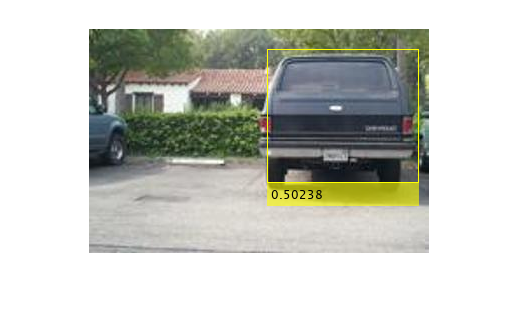

I = imread(testData.imageFilename{18});
[bboxes, scores] = detect(detector, I);
if ~isempty(bboxes)
    % Object detected!
    I = insertObjectAnnotation(I, 'rectangle', bboxes, scores);
end
imshow(I)

### **Evaluate Detector Using Test Set**

Evaluate the detector on a large set of images to measure the trained detector's performance.

The first step for detector evaluation is to collect the detection results by running the detector on the test set.  Create a table to hold the bounding boxes, scores, and labels output by the detector. 

numImages = height(testData);
results = table('Size', [numImages 3], ...
    'VariableTypes', {'cell', 'cell', 'cell'}, ...
    'VariableNames', {'Boxes', 'Scores', 'Labels'});

Run detector on each image in the test set and collect results.

for ii = 1:numImages    
    % Read the image.
    I = imread(testData.imageFilename{ii});
    
    % Run the detector.
    [bboxes, scores, labels] = detect(detector, I);
    
    % Collect the results.
    results.Boxes{ii} = bboxes;
    results.Scores{ii} = scores;
    results.Labels{ii} = labels;
end

% Extract expected bounding box locations from test data.
expectedResults = testData(:, 2:end);

% Evaluate the object detector using average precision metric.
[ap, recall, precision] = evaluateDetectionPrecision(results, expectedResults);

### Evaluation Metric - Precision / Recall Curve

The precision/recall (PR) curve highlights how precise a detector is at varying levels of recall. Ideally, the precision would be 1 at all recall levels. The use of additional layers in the network can help improve the average precision, but might require additional training data and longer training time.

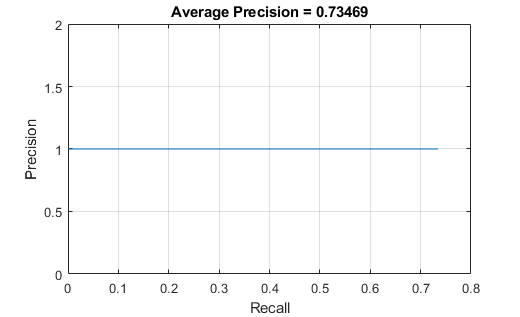

plot(recall, precision)
xlabel("Recall")
ylabel("Precision")
grid on
title("Average Precision = " + ap)